# Fourier Edge Math

## Setting up the workspace

clear;
addpath( 'C:\Users\johns\Documents\Github\QEM-MATLAB');
addpath( 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0\', ...
         'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter');
load('ImpVariables.mat');
load('200728 xGAN Symmetric Kimball Sweep v4.mat')

## Definition of time and variables

time = interpTimeDbl(1:end-1)  %Removing last time point

time = 	1.0e+-7 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


n = size(time)

n =            1        2000


n = n(2)

n = 2000

t_res  = time(2)-time(1); % temporal resolution
f_res = 1/t_res;
t_rep = interpTimeDbl(end) -time(1); %Rep rate shifted up to real value
f_rep = 1/t_rep;
fP = linspace(-f_res/2,f_res/2,n)

fP = 	1.0e+10 *

   -1.0000   -0.9990   -0.9980   -0.9970   -0.9960   -0.9950   -0.9940   -0.9930   -0.9920   -0.9910   -0.9900   -0.9890   -0.9880   -0.9870   -0.9860   -0.9850   -0.9840   -0.9830   -0.9820   -0.9810   -0.9800   -0.9790   -0.9780   -0.9770   -0.9760   -0.9750   -0.9740   -0.9730   -0.9720   -0.9710   -0.9700   -0.9690   -0.9680   -0.9670   -0.9660   -0.9650   -0.9640   -0.9630   -0.9620   -0.9610   -0.9600   -0.9590   -0.9580   -0.9570   -0.9560   -0.9550   -0.9540   -0.9530   -0.9520   -0.9510


## Select Function and plot it

%fn2plot selects the array in the time base we want to plot
dampIndex = 1; % chooses which damping we are using
stepR(1)

ans = int32
1

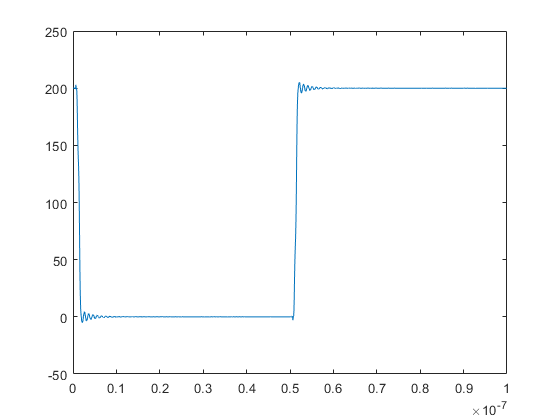

fn2plot = interpVoltAllDbl(dampIndex,1:end-1);
plot(time,fn2plot);

## Fourier Transform

fn_FFT = fft(fn2plot);
fn_FFT_normal = fftshift(fn_FFT)

fn_FFT_normal = 	1.0e+05 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


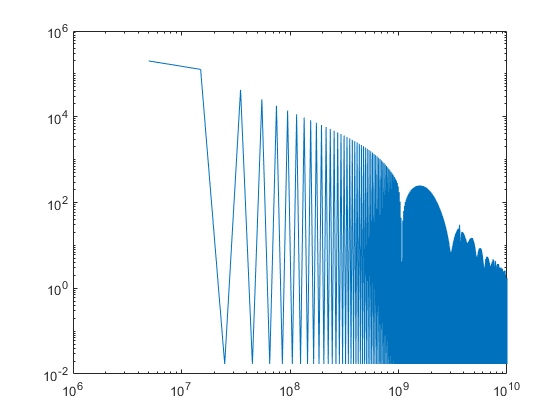

loglog(fP,abs(fn_FFT_normal))

% fmin = 0;
% fmax = 4*c.giga;
% xlim([fmin, fmax]);
% G_FFT = fft(Gaussian, n);
% P = abs(G_FFT/n);


## Inverse Fourier Transform

invFnFFT = ifft(fn_FFT);
plot(time,invFnFFT);

## Plotting Settings

% x0=0;
% y0=0;
% width=1000;
% height=750;
% 
% set(gcf,'position',[x0,y0,width,height])
% set(gcf,'DefaultLineLineWidth',3)
% set(gca,'FontSize',25)
% grid on;
% grid minor;
